# Aerogen Exercise

## VARIABLES AND PARAMETERS FOR THE SIMULINK MODEL


Vw=10;      % Wind speed [m/s]
Tf=0.1;     %
Ke=1.3717;  %
Bm=0.001;   % 
J=0.1;      %
R=10;       %
Ra=2.58;    %
La=0.028;   %
Rpala=1.6;  %
Rho=1.225;  %


coefficients for lambda


c1=0.51763;
c2=116;
c3=0.4;
c4=5;
c5=21;
c6=0.006795;


Parameters of actuator

wnAct=20; 
psiAct=0.8;
maxDefAct = 0;
minDefAct = -70;
rateLimAct = 50;
initialPosAct = 0; 
initialVelAct = 0;


## TRIMING THE PLANT

 To find the triming point of the plant a new model of the aerogen is generated without the actuator, the actuator makes the trim algorithm to fail (CHECK THIS!) 

 Select the point around the trim will be done:

X0 = [50;5.5];  % initial condition for the states (in this case angular speed and electrical generator intensity) 
Y0 = [50];      % initial condition on y -> angular speed
U0 = [];        % initial condition on u -> whatever


Fix some of the components of X, Y or U in the triming process:

iy = [1];       % Constrain Y(1) to be fixed
ix = [];        % No constrain over x
iu = [];        % No constrain over u

Find the triming point on the condition especified above

[X,U,Y,DX,options] = trim('Aerogen2019NoActuator',X0,U0,Y0,ix,iu,iy);

%% LINEARIZE THE PLANT

% Generate the vector state
Xlin = [X(1);U;0;X(2)];

%Edit initial position and speed of actuator
initialPosAct = U;
initialVelAct = 0;

trimIntensity = X(2);


[num,den] = linmod('Aerogen2019',Xlin,U);
%[num,den] = linmod('Aerogen2019NoActuator',X,U)


## DYNAMIC RESPONSE

First generate the transfer function

transferFunction = tf(num,den);
% Zeros and poles of tf
zeros = zero(transferFunction);
poles = pole(transferFunction);

 **Locus of roots of the system:**

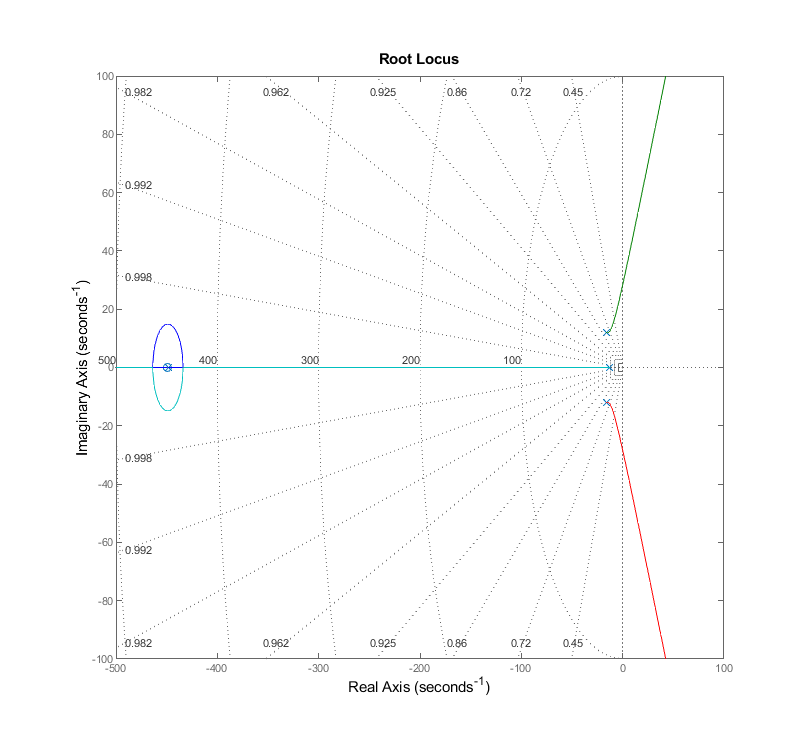

f1 = figure(1);
rlopt.XLim = {[-500 100]};
rlopt.YLim = {[-100 100]};
rlopt.Grid ='on';
rlocusplot(transferFunction, rlopt);

**Bode Diagram:**

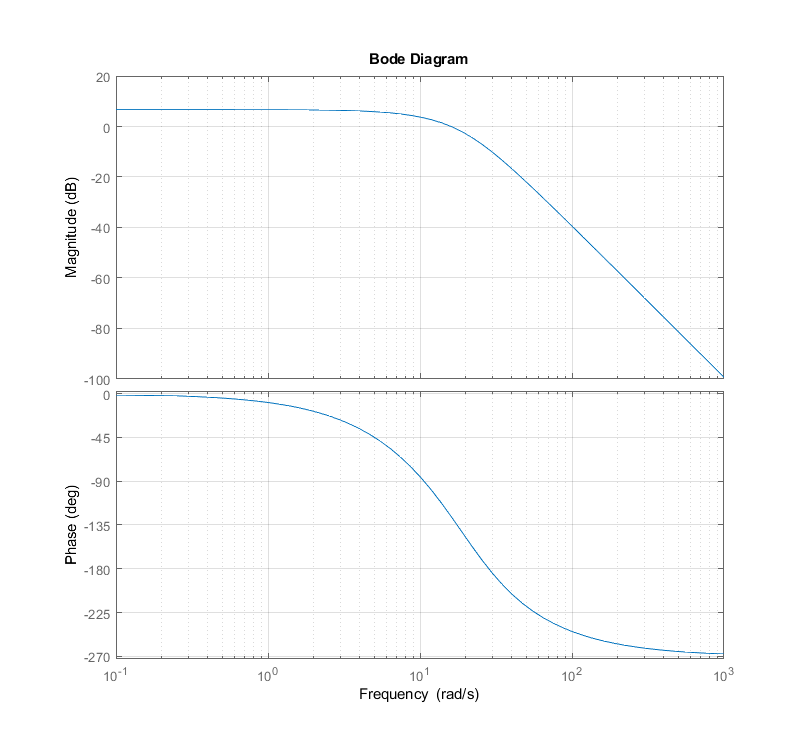

f2 = figure(2);
bode(transferFunction)
grid on

**Nyquist Diagram: **

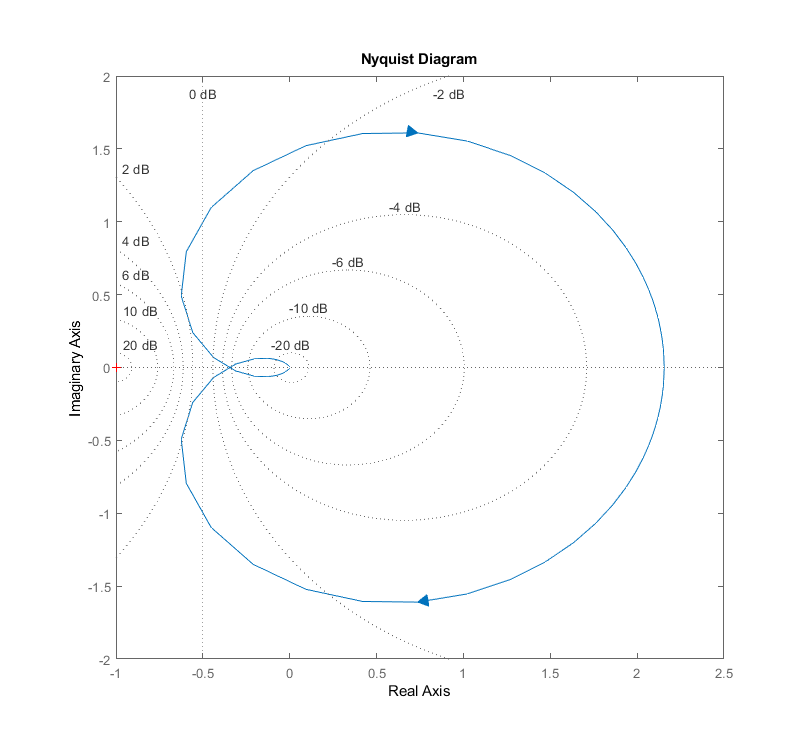

f3 = figure(3);
nyquist(transferFunction)
grid on

**Step Response:**

f4 = figure(4);
set(f4,'Position',[10 10 800 800])
set(f4,'DefaultAxesFontSize',20)
step(transferFunction)
grid on
hold on

Compare the step response of linear system with real system: for this task a new simulink model is generated, all integrators are set to its trim point value and an unitary step is generated at t=0 of the simulation. 

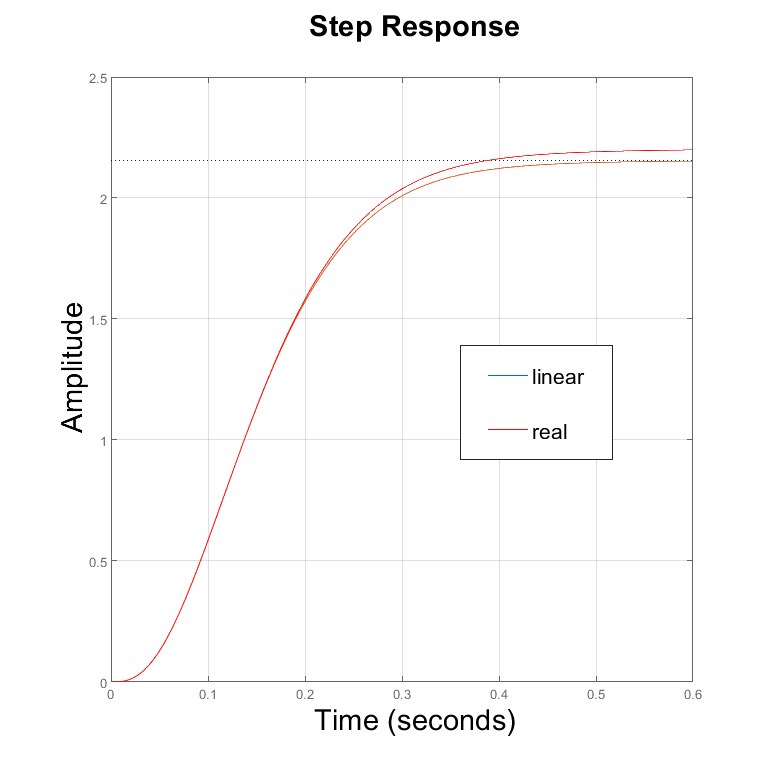

simOut = sim('Aerogen2019Step','OutputSaveName','yout');
outputs = simOut.get('yout');
% Once the simulation is done the result si plotted against the step
% response of the linear system.

plot(outputs(:,2),outputs(:,1),'r')
legend({'linear','real'},'FontSize',16,'Position',[0.6 0.4 0.2 0.15])